## Synthesis of Robust and stable controler from Desired response 

### Initizilation

clc
clear
disp("Initilization Procedure")

Initilization Procedure


model.Parameters
param.ctrl.T_ref = util.Celsius2Kelvin(20);

T_kelvin = 293.1500

param = control.calculateOperatingPoint(param);

Calculate Operating Point for T_a = 293.150000 [K]

param = model.calculateModel(param);

Calculate bilinear model matrices
Calculate linearisation decoupled
Calculate linearisation coupled
Testing controlability
Testing T_ref


param = model.calculateWDelta(param,0);

### Filter

The controller is designed with only Wref, Wu =0 

%Wref
%lowpass filter wich result in a setling time of 10 min (600 sec) .  
s=tf('s');
wref =eye(4)*(1/(120*s+1));
wrefSS = ss(wref);
param.model.AWref = wrefSS.A; 
param.model.BWref = wrefSS.B;
param.model.CWref = wrefSS.C;
param.model.DWref = wrefSS.D;

%Wu set to 0 to not take u into the syntehsis procces
param.model.AWu = zeros(4); 
param.model.BWu = zeros(4);
param.model.CWu = zeros(4);
param.model.DWu = 0*eye(4);

### Control

param = control.DesignProcedureFWMM(param,0); 

Evaluation of design procedure for Frequency weighted model matching 
Gamma is found to be: 0.229495 


### Simulate the linear response

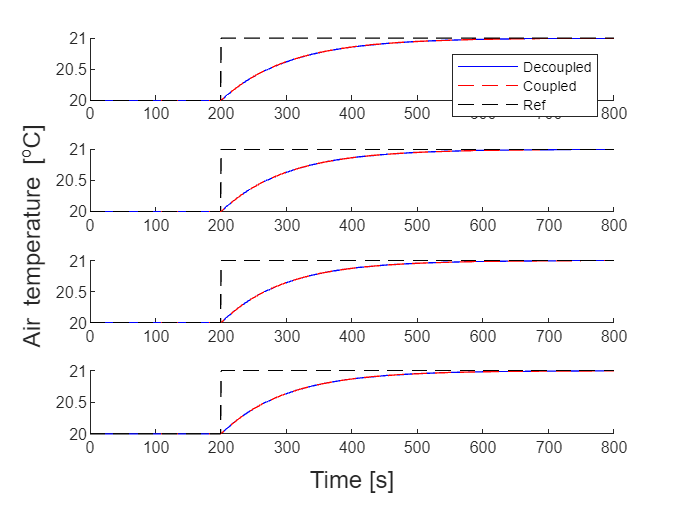

util.SimulateLinearStep(param,"Synthesis_Of_DesiredPerformance_Only_Wref",0,800);

### Adjusting the response

We adjust Dwz, so the error is penalized more

param.model.Dwz = 20*eye(4);
param = control.DesignProcedureFWMM(param,0); 

Evaluation of design procedure for Frequency weighted model matching 
Gamma is found to be: 0.229495 


### Simulate the linear response

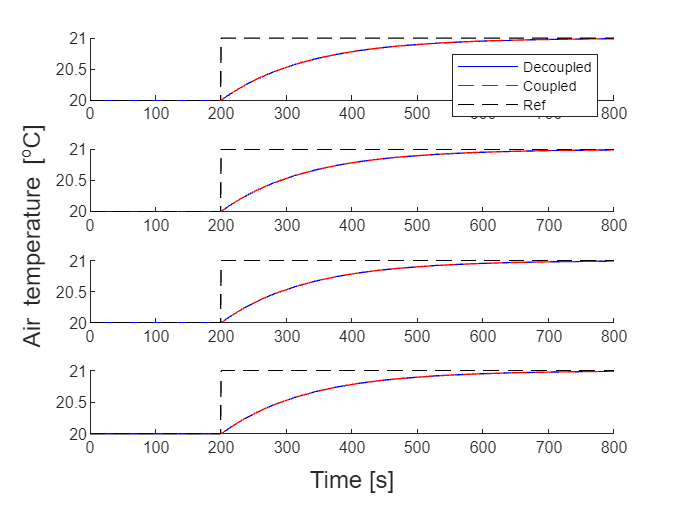

util.SimulateLinearStep(param,"Synthesis_Of_DesiredPerformance_Wref_and_Wz",0,800);

### Investigate the actuation and flow used

[~, CoupledResults] = util.SimulateLinearStep(param,"Synthesis_Of_DesiredPerformance_Only_Wref_fitted_30",0,800);

figure()
plot(CoupledResults.time,CoupledResults.q'*3600);
legend("q AHU1","q AHU2","q AHU3","q AHU4")
xlabel("Time [s]")
ylabel("Flow m^3/h")
saveas(gcf,"Images/FlowIncreaseTempBy10Deg","epsc")

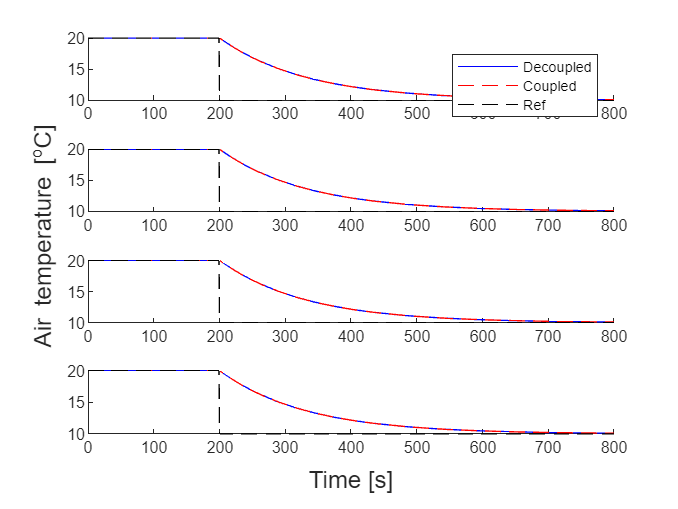

[decoupleResult, CoupledResults] = util.SimulateLinearStep(param,"Synthesis_Of_DesiredPerformance_Only_Wref_fitted_10",0,800,-10);

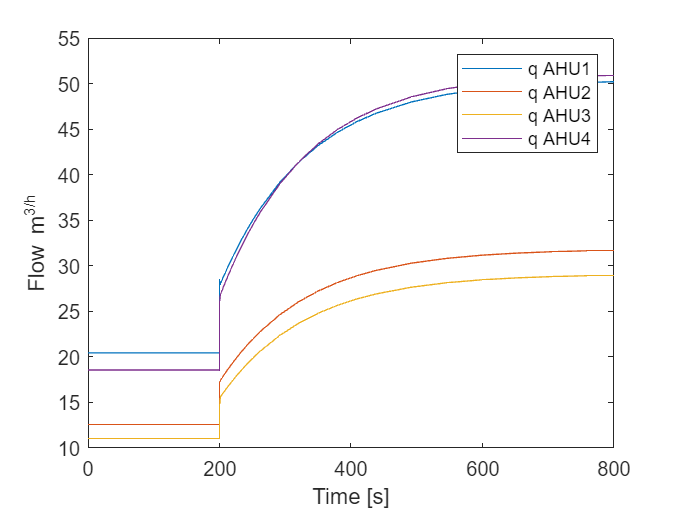

figure()
plot(CoupledResults.time,CoupledResults.q'*3600);
legend("q AHU1","q AHU2","q AHU3","q AHU4")
xlabel("Time [s]")
ylabel("Flow m^3/h")
saveas(gcf,"Images/FlowLowerTempBy10Deg","epsc")